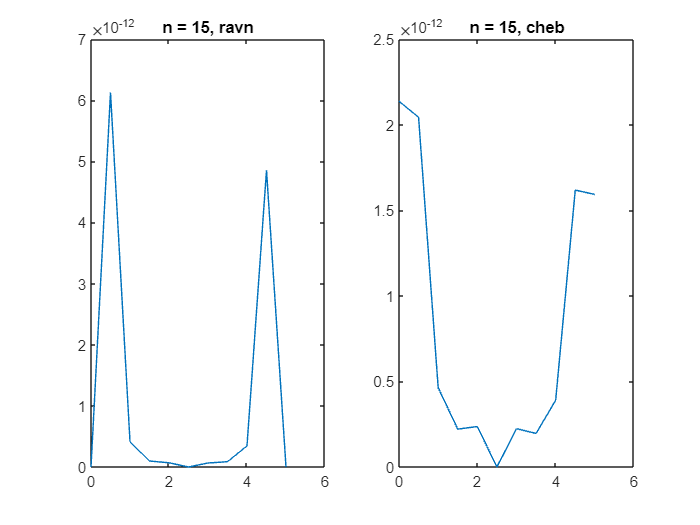

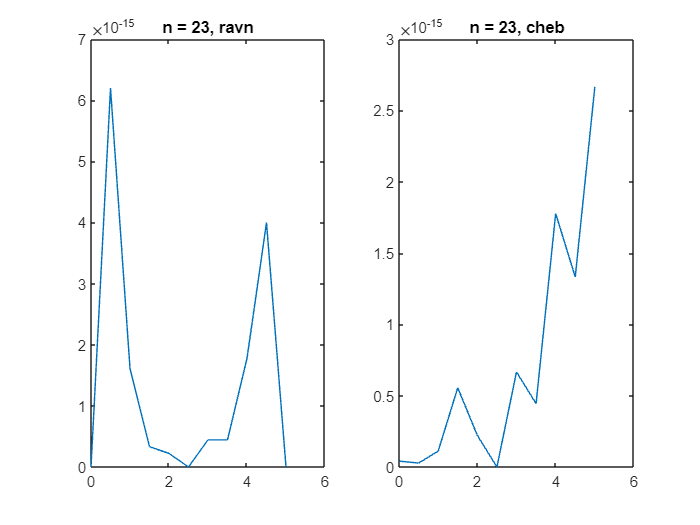

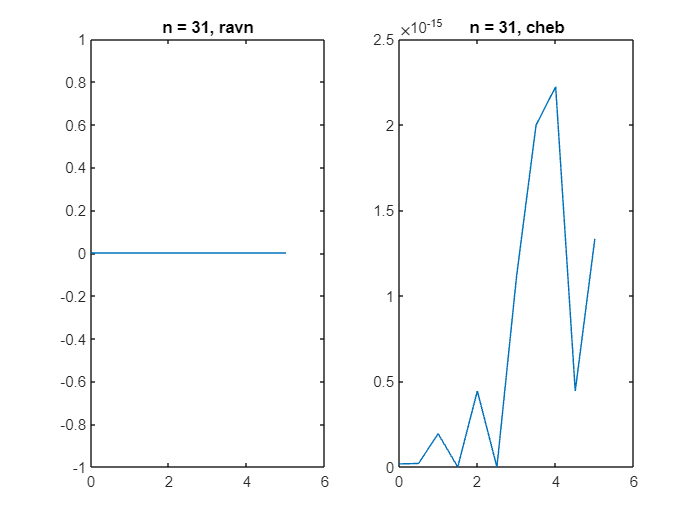

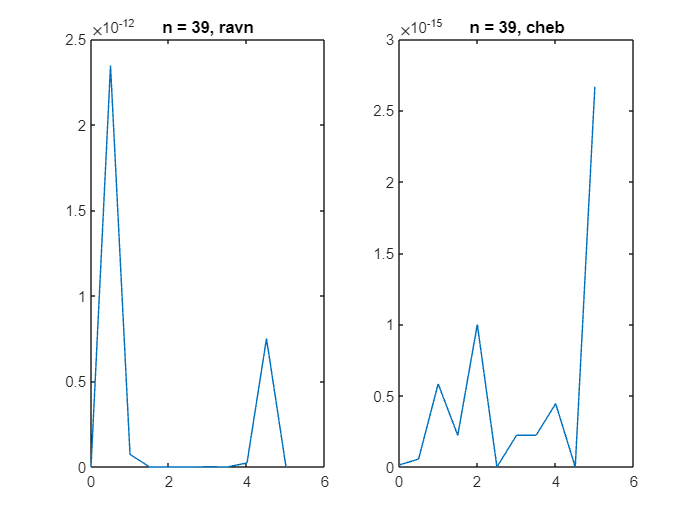

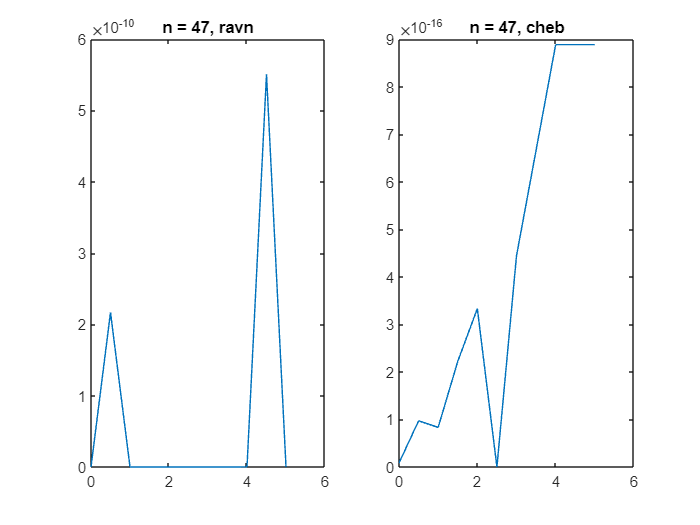

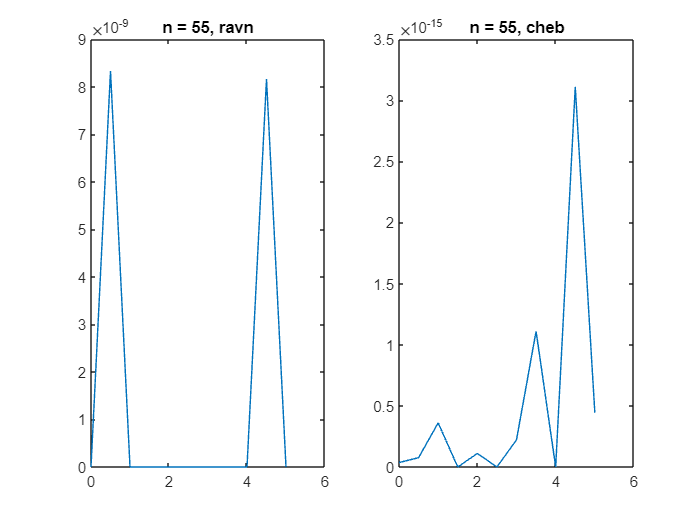

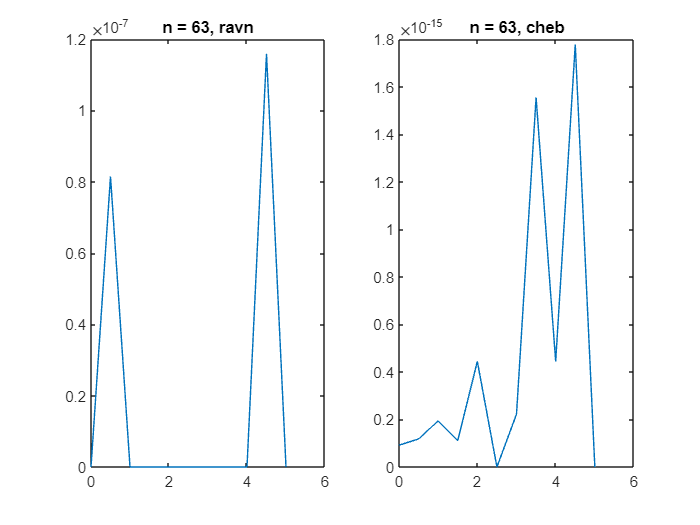

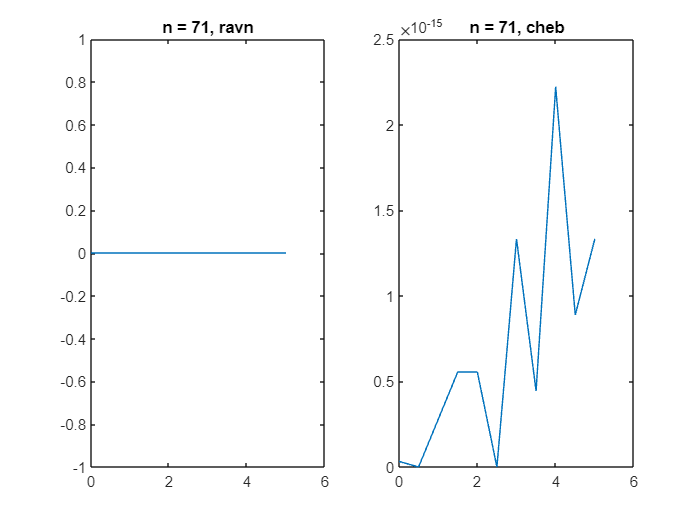

close all
clear all
clc
x = 0:0.5:5;
e = 1e-15;
yt = intcos(x, e);
n = [15:8:100];

eNp = zeros(1,numel(n));
eNch = eNp;
for i = 1:numel(n)
    xsp = linspace(0, 5, n(i));
    fp = intcos(xsp);
    xsc = cheb(0, 5, n(i));
    fc = intcos(xsc);
    yp = pol(x, xsp, fp);
    yc = pol(x, xsc, fc);
    ep = abs(yp - yt);
    ec = abs(yc - yt);
    eNp(i) = max(ep);
    eNch(i) = max(ec);
    figure
    subplot(1,2,1);
    plot(x, ep);
    title(['n = ' num2str(n(i)) ', ravn'])
    subplot(1,2,2);
    plot(x, ec);
    title(['n = ' num2str(n(i)) ', cheb'])
end

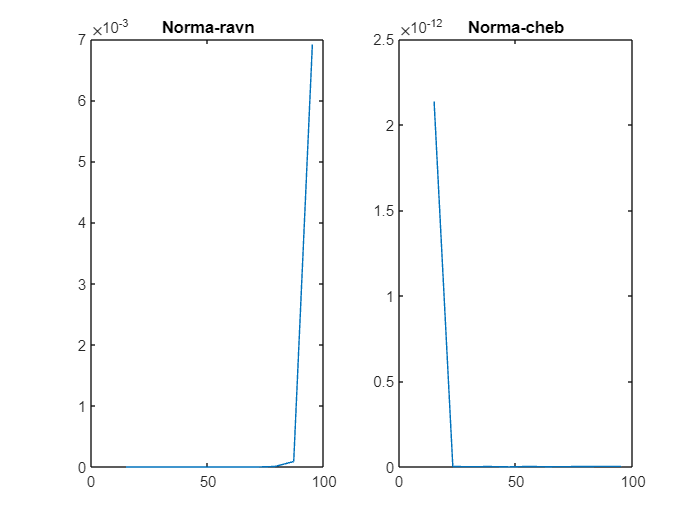

figure
subplot(1,2,1);
plot(n, eNp);
title(['Norma-ravn'])
subplot(1,2,2);
plot(n, eNch);
title(['Norma-cheb'])

Интегральный косинус:

function [y,ki] = intcos(x,e)
y = zeros(size(x));
kmax = 100;
if nargin == 1
    e = 1e-15;
end
if nargout == 2
    ki = y;
end
for i = 1:numel(x)
    a = -x(i)*x(i)/4;
    sum = a;
    k = 1;
    while(abs(a) >= e) && (k < kmax)
        q = -x(i) * x(i) * k / ((k + 1) * (2 * k + 1 ) * (2 * k + 2));
        k = k + 1;
        a = a* q;
        sum = sum + a;
    end
    y(i) = sum;
    if nargout == 2
        ki(i) = k;
    end
end
end

Чебышевкая сетка:

function [xsc] = cheb(a, b, n)
xsc = zeros(1,n);
for i = 1:n
    xsc(i) = (b - a) / 2 * cos((2*i - 1)*pi/(2*n)) + (a + b)/2;
end
end

Высчитываем полином:

function [y] = pol(x, xs, f)
y = zeros(size(x));
for t = 1:numel(x)
    sum = 0;
    for i = 1:numel(f)
        pr = 1;
        for j = 1:numel(f)
            if i ~= j
                pr = pr*(x(t) - xs(j))/ (xs(i) - xs(j));
            end
        end
        sum = sum + f(i)*pr;
    end
    y(t) = sum;
end
end

**Вывод**

    Равномерная сетка при малых n даёт хорошую точность, как на втором рисунке равномерной сетки, но при увеличении точек точность приближения падает. С другой стороны, Чебышевская сетка выдаёт стабильную точность как при малом n, так и при увеличении n.